# Kernel-based Estimators

clear
load('dgp.mat')
[n,k]= size(X);
h=1;

## OLS


$$m = X(X'X)^{-1}X'Y$$


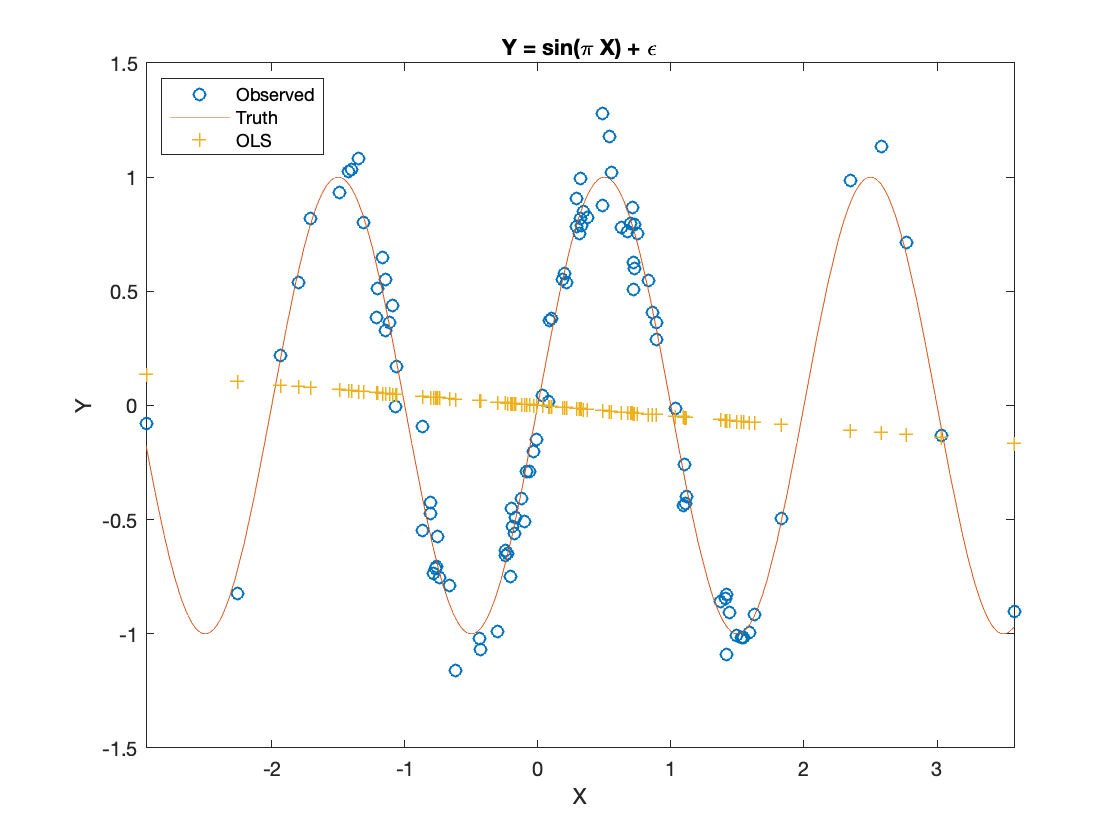

ols = X*(X'*X)^-1*X';
Y_hat = ols*Y;

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
plot(X,Y_hat,'+');
legend('Observed', 'Truth', 'OLS','Location','Northwest');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)])
hold off;


ols_df1 = trace(ols)

ols_df1 = 1

ols_df2 = n-trace(2*ols -ols*ols')

ols_df2 = 99

ols_df3 = trace(ols*ols')

ols_df3 = 1.0000

ols_df4 = trace(eye(size(ols))-ols)

ols_df4 = 99.0000

cond_OLS = norm(ols)*norm(ols^-1)

cond_OLS = 1.1971e+22

## Nadaraya-Watson


$$\hat{m}(x_0) = \frac{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)y_l}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)}$$
 

$\hat{Y}_{NW} = KY$, with elements $k_{i,j} = \frac{k\Big(\frac{x_j-x_i}{h}\Big)}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_i}{h}\Big)}$ 

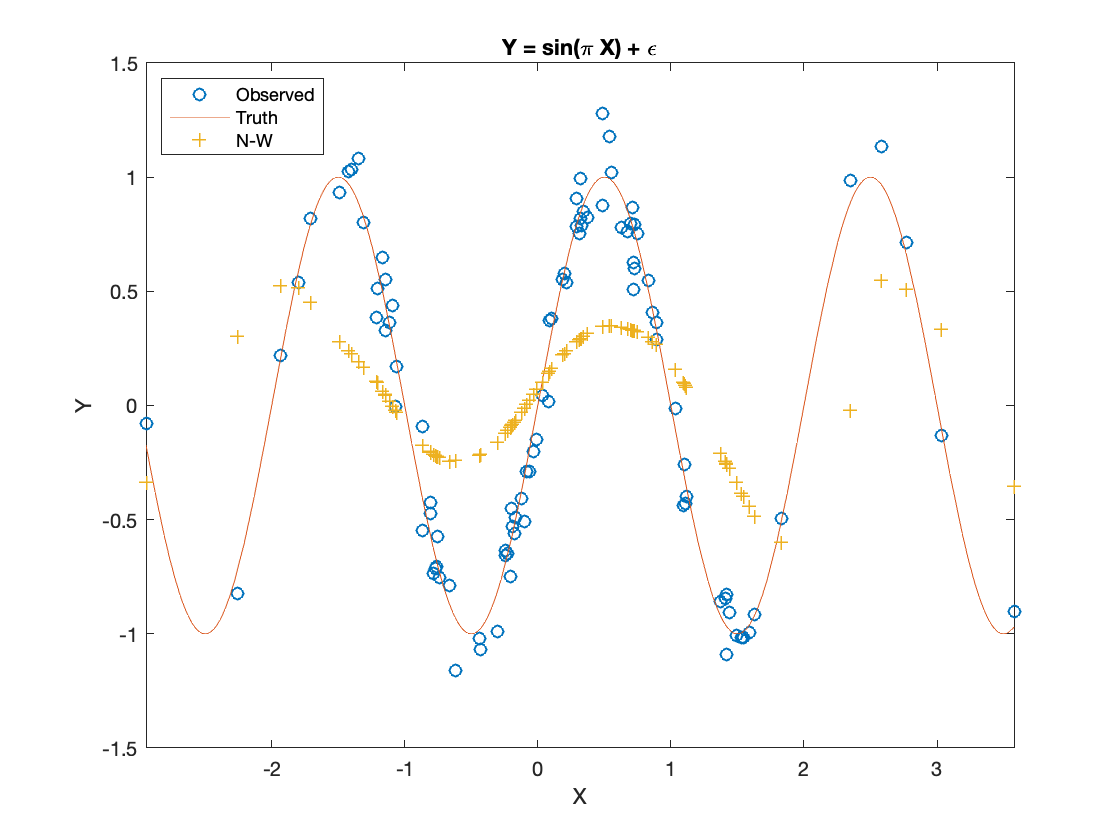

% diff_ij = (x_j-x_i)/h
diff = (repmat(X',n,k)-repmat(X,k,n))/h;
%Epanechnikov kernel
numerator = 3/4*(ones(n*k)-diff.^2).*(abs(diff)<=1);
denominator = repmat(sum(numerator,2),k,n);
K = numerator./denominator;

Y_NW = K*Y;

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
plot(X,Y_NW,'+');
legend('Observed', 'Truth', 'N-W','Location','Northwest');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)]);
hold off;



nw_df1 = trace(K)

nw_df1 = 5.2092

nw_df2 = n-trace(2*K -K*K')

nw_df2 = 93.7780

nw_df3 = trace(K*K')

nw_df3 = 4.1963

nw_df4 = trace(eye(size(K))-K)

nw_df4 = 94.7908

cond_NW = norm(K)*norm(K^-1)

cond_NW = 1.1354e+19

## Local Linear

$\tilde{m}(x_0) = [\mathbf{1_n} \enspace X_0]\big([\mathbf{1_n} \enspace X_0]'W_0[\mathbf{1_n} \enspace X_0]\big)^{-1}[\mathbf{1_n} \enspace X_0]'W_0Y$, where $X_0 = [X-x_0\mathbf{1_n} ]$ and $W_0 = diag[k\Big(\frac{x_1-x_0}{h}\Big), ... ,k\Big(\frac{x_n-x_0}{h}\Big)]$ 

$\hat{Y}_{LL} = LY$, with row i given as the i'th row of $[\mathbf{1_n} \enspace X_i]\big([\mathbf{1_n} \enspace X_i]'W_i[\mathbf{1_n} \enspace X_i]\big)^{-1}[\mathbf{1_n} \enspace X_i]'W_i$

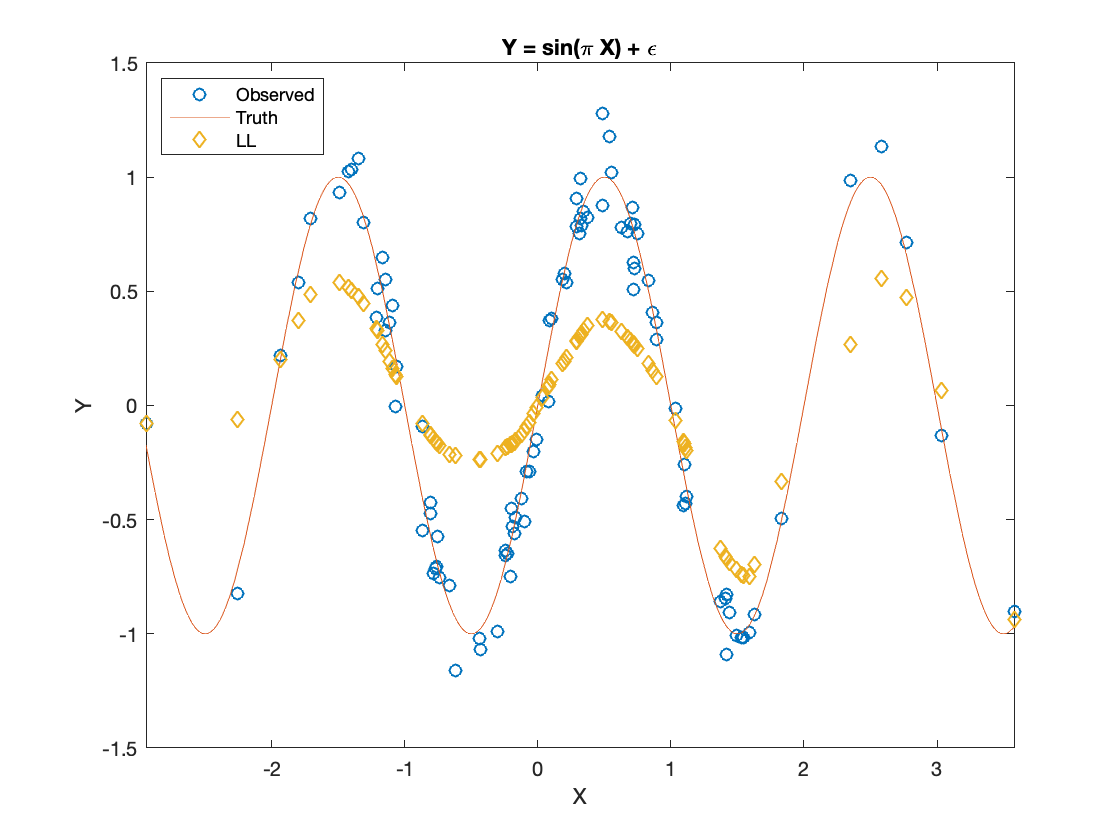


L = zeros(n,n);

% diff_ij = (x_j-x_i)
diff = (repmat(X',n,k)-repmat(X,k,n));
%Epanechnikov kernel
kn = 3/4*(ones(n*k)-(diff/h).^2).*(abs(diff./h)<=1);
nOnes = ones(n,1);
for i=1:n
    x = [nOnes diff(i,:)']; 
    w = diag(kn(i,:));
    proj = x*(x'*w*x)^-1*x'*w;
    L(i,:)=proj(i,:);
end

Y_LL = L*Y;

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
plot(X,Y_LL,'d');
legend('Observed', 'Truth', 'LL','Location','Northwest');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)])
hold off;



ll_df1 = trace(L)

ll_df1 = 6.9828

ll_df2 = n-trace(2*L -L*L')

ll_df2 = 92.1957

ll_df3 = trace(L*L')

ll_df3 = 6.1612

ll_df4 = trace(eye(size(L))-L)

ll_df4 = 93.0172

cond_LL = norm(L)*norm(L^-1)

cond_LL = 3.5062e+18

2 things need to take into account:

condition number very dependent on h and number of knots

also perhaps on functions use to calculate functions for estimator

spline: knots and some other parameter

series estimator

choice of h, knots, etc

non-stochastic choice of h,k (not data dependent) tensor product-ish

and/or

stochastic choices, (data driven)

- need theory that relates condition number to smoothness imparting on estimation of regressors

leverage in linear models 

## Specification help

Nadaraya-Watson: [https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf](https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf) and [http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf](http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf) (cause I can't put my hands on the notes from Fall 2017)

Local linear: [http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf](http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf)